## **Przetwarzanie Sygnałów Cyfrowych**

# **Filtracja sygnałów, Filtry IIR**

## Jan Rosa 410269 AiR

### Zadania do wykonania

W sprawozdaniu powinny znaleźć się:

1) Informacje na temat w jaki sposób projektujemy filtry IIR.

2) Różnice między filtrami FIR i IIR.

3) Wykonane zadania - skrypty w m.plikach oraz otrzymane wykresy.

4) Wnioski z przeprowadzonych zadań.

### Zad. 1

Korzystając z Przykładu 4 zaprojektować filtr IIR:

[b,a] = maxflat(4,1,0.3)

oraz

maxflat(4,'sym',0.3)

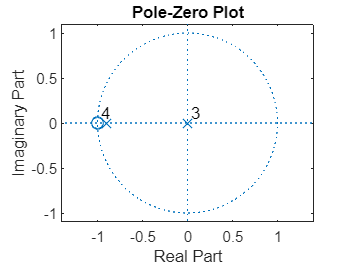

clear all; close all;
[b,a] = maxflat(4,1,0.3);
zplane(b ,a)

%fvtool(b,a);

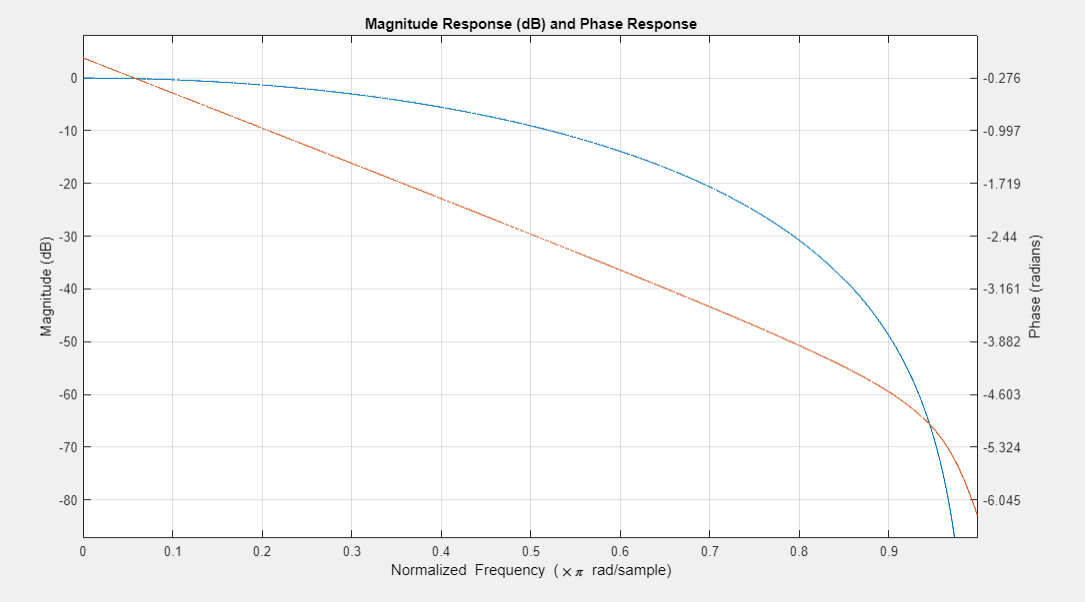

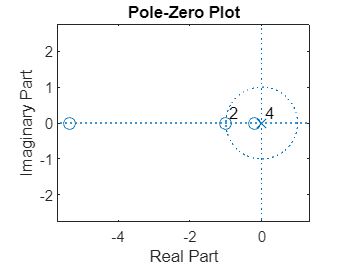

[b,a] = maxflat(4,'sym',0.3);
zplane(b ,a)

%fvtool(b,a)

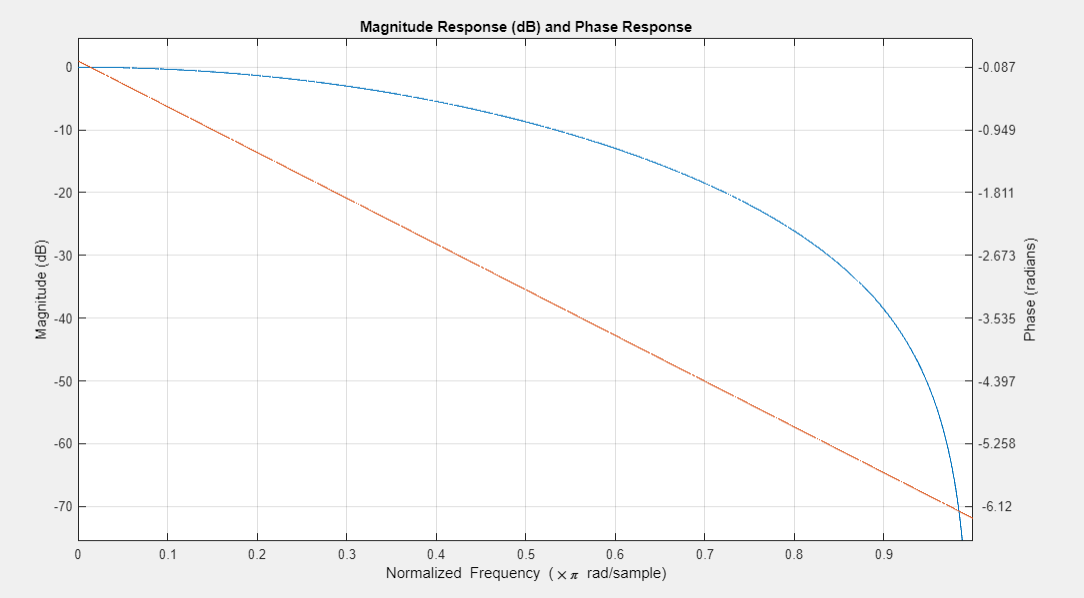

### Zad2

Sprawdzić stabilność filtru o współczynnikach 

b = [1 -0.5]; a = [1 -2];
zplane(b ,a)
isstable(b,a)

### Zad3

Sprawdzić stabilność filtru o współczynnikach 

b = [1 -0.1]; a = [-1 -0.1];
zplane(b ,a)
isstable(b,a)

### Zad4

Sprawdzić stabilność filtru o współczynnikach

b = [0.9 -0.8]; a = [-0.9 -0.8];
zplane(b ,a)
isstable(b,a)

### Zad5

Sprawdzić stabilność filtru o współczynnikach

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
zplane(b ,a)
isstable(b,a)

### Zad6

Sprawdzić stabilność następującego filtru

m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b, a] = yulewalk(10, f, m);
zplane(b ,a)
isstable(b,a)

### Zad7

Przefiltrować sygnał chirp filtrem IIR maxflat(4,1,0.3). Narysować przebieg

czasowy i częstotliwościowy przefiltrowanego sygnału.

[b, a] = maxflat(4,1,0.3);
act_flag1 = isstable(b,a)
%zplane(b,a)
% wynik flag = 0
load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);
subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad8

Przefiltrować sygnał chirp filtrem IIR

m = [0 0 0 0 0 1 1 1 1 1];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
act_flag1 = isstable(b,a)
%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)
load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);
subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

Zad 9

Przefiltrować sygnał chirp filtrem IIR. Uwaga filtr jest niestabilny.

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];

Narysować przebieg czasowy i częstotliwościowy przefiltrowanego sygnału.

Narysować charakterystykę częstotliwościową filtru.

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
act_flag1 = isstable(b,a)
%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

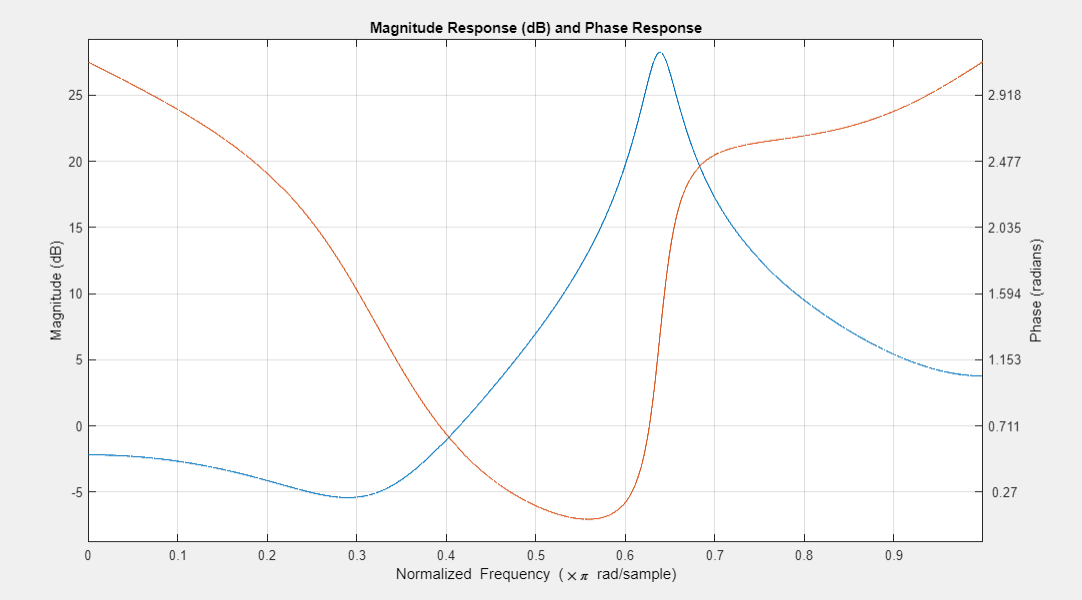

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 10

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji buttord i butter.

z parametrami

[n,Wn] = buttord([2000 3000]/5000,[500 4500]/5000,1,60);
[b, a] = butter(n, Wn);
act_flag1 = isstable(b,a)
%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

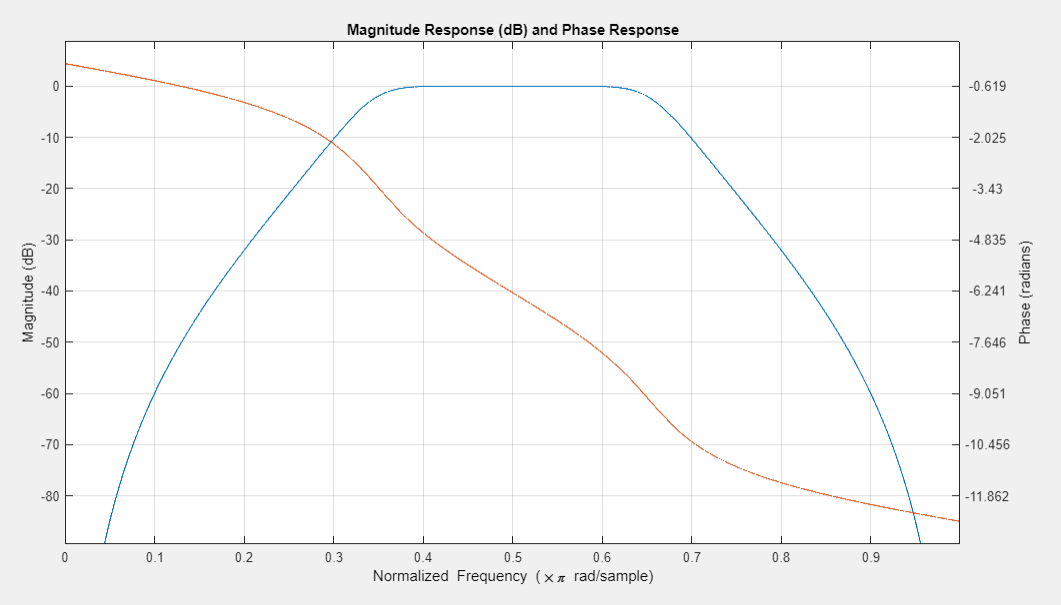

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 11

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji buttord i butter.

z parametrami

[n,Wn] = buttord([2000 3000]/5000,[1800 3200]/5000,1,60);
[b, a] = butter(n, Wn);
act_flag1 = isstable(b,a)
%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

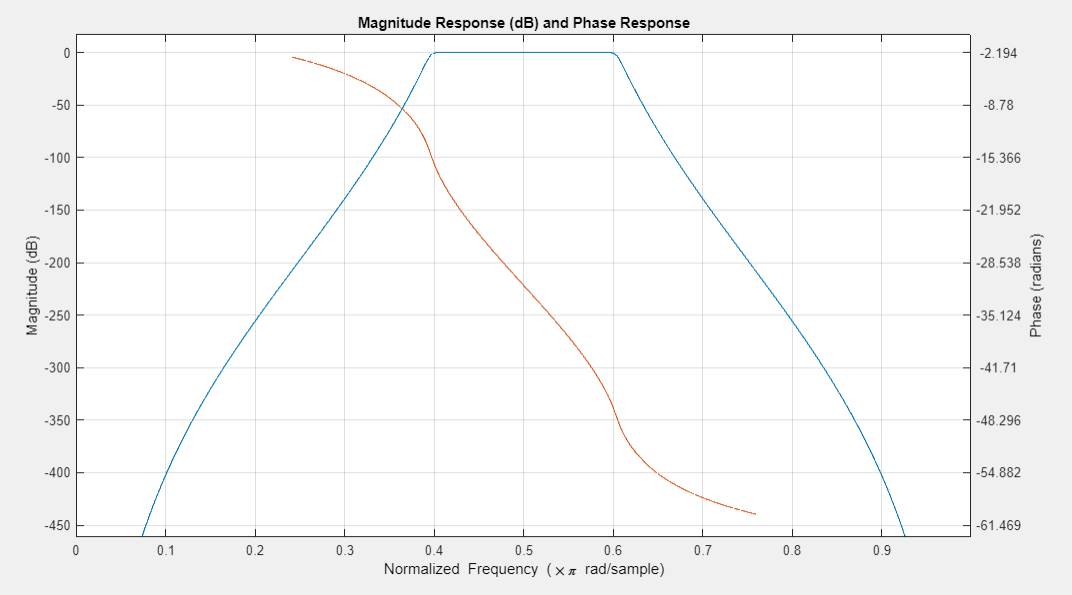

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 12

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji ellipord i ellip.

z parametrami

[n,Wn] = ellipord([2200 2700]/5000,[2000 2900]/5000,1,60);
[b, a] = ellip(n,1 , 60, Wn);
act_flag1 = isstable(b,a)
%zplane(b,a)
%wynik flag = 0
%fvtool(b,a)

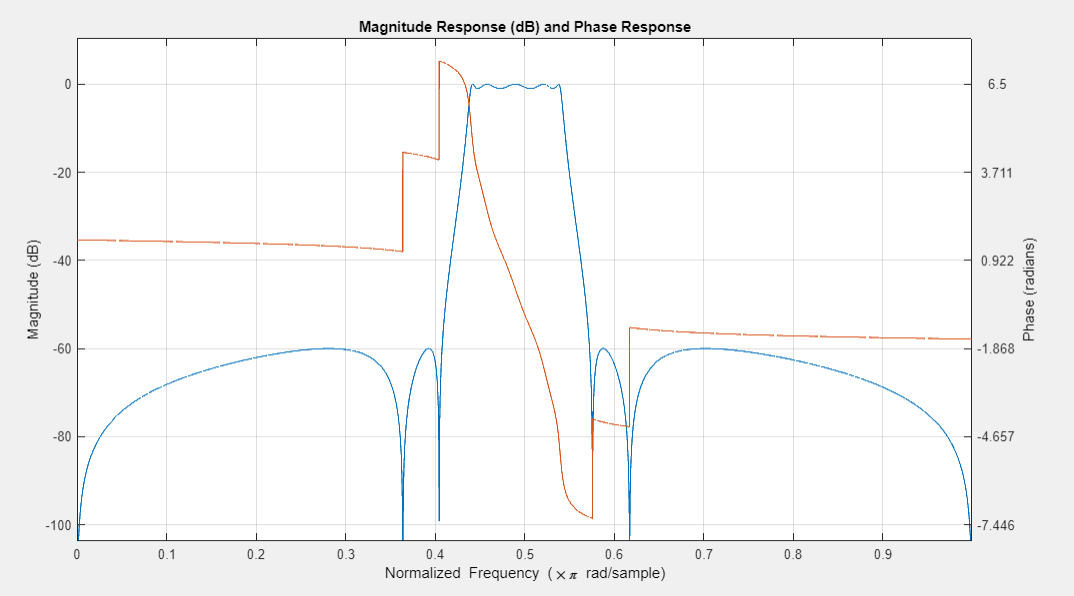

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));

### Zad 13

Przefiltrować sygnał chirp filtrem IIR, eliptycznym. Użyć funkcji ellipord i ellip.

z parametrami

[n,Wn] = ellipord([1000 4000]/5000,[900 4100]/5000,1,60)
[b, a] = ellip(n,1 , 60, Wn);
act_flag1 = isstable(b,a)
%zplane(b,a)
%wynik flag = 0
%fvtool(b,a)

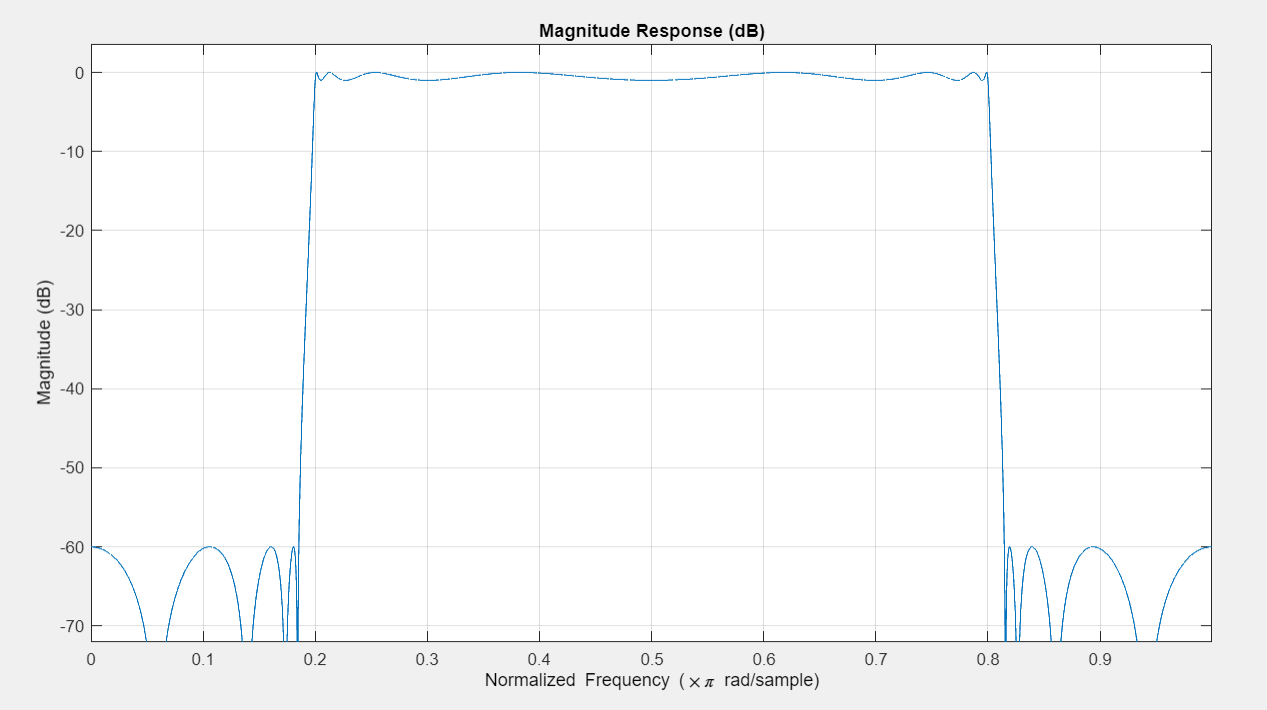

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));

### Zad 14

Przefiltrować sygnał chirp filtrem dolnoprzepustowym Butterwortha z zastosowaniem funkcji butter(), sosfilt().

load chirp
t = (0:length(y)-1)/Fs;
[zhi,phi,khi] = butter(7,0.48,'low');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi);
outhi = sosfilt(soshi,y);

figure
subplot(3,1,1)
plot(t,y); grid on;
title('Original Signal')
xlabel('Time (s)')
ys = ylim;

subplot(3,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal (time)');grid on;
xlabel('Time (s)')
ylim(ys)

subplot(3,1,3)
xfft = abs(fft(outhi));
xfft = xfft/13129;
x1 = 1:1:6564;
bar(x1(1:6564), xfft(1:6564)); grid on; xlabel("Frequency [Hz]"); title("Lowpass=Filtred Signal (Frequency)")

### Zad 15

Przefiltrować sygnał chirp filtrem górnoprzepustowym Butterwortha z zastosowaniem funkcji butter(), sosfilt().

load chirp
t = (0:length(y)-1)/Fs;
[zhi,phi,khi] = butter(7,0.48,'high');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi);
outhi = sosfilt(soshi,y);

figure
subplot(3,1,1)
plot(t,y); grid on;
title('Original Signal')
xlabel('Time (s)')
ys = ylim;

subplot(3,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal (time)');grid on;
xlabel('Time (s)')
ylim(ys)

subplot(3,1,3)
xfft = abs(fft(outhi));
xfft = xfft/13129;
x1 = 1:1:6564;
bar(x1(1:6564), xfft(1:6564)); grid on; xlabel("Frequency [Hz]"); title("Highpass=Filtred Signal (Frequency)")

### Odpowiedzi

#### 1) Informacje na temat w jaki sposób projektujemy filtry IIR.

    W przypadku projektowania filtrów FIR wystarczyło zdefiniować funkcję transmitancji (czyli de facto określić charakterystykę częstotliwościową filtru), obliczyć odwrotną transformatę Fouriera tej funkcji, wynik transformaty poddać przesunięciu, i uzyskiwaliśmy odpowiedź impulsową filtru w dziedzinie czasu. W przypadku filtru IIR pożądane współczynniki filtru h(k) są dokładnie równe wartościom poszczególnych próbek odpowiedzi impulsowej. W przypadku filtrów IIR możemy postąpić tak samo (tzn. określić pożądaną funkcję transmitancji i obliczyć jej odwrotną transformatę Fouriera, aby uzyskać odpowiedź impulsową filtru), jednakże zła wiadomość jest taka, że nie ma bezpośredniej metody obliczenia współczynników a(k) i b(k) z odpowiedzi impulsowej. A więc stosunkowo proste techniki projektowania filtrów FIR nie mogą być zastosowane do projektowania filtrów IIR. Nie ma to jednak wielkiego znaczenia, bo obecnie nikt nie projektuje filtrów cyfrowych z kartką i ołówkiem w ręku, wykonując mniej lub bardziej żmudne obliczenia. Obecnie wszystko to wykonuje komputer (za pomocą odpowiedniego oprogramowania), a nasze zadanie ogranicza się tylko do wpisania pożądanych parametrów, jakimi ma wykazywać się nasz filtr.

#### 2) Różnice między filtrami FIR i IIR.

    Zła wiadomość jest taka, że nie ma takiej jednoznacznej odpowiedzi, który filtr jest lepszy. Nawet gdybyśmy chcieli wybrać jeden z filtrów do konkretnych struktur cyfrowych też trudno jednoznacznie orzec, że ten będzie OK, a tamten nie za bardzo. Spróbujmy jednak wskazać kilka czynników, które pozwolą nam dokonać takiego wyboru.

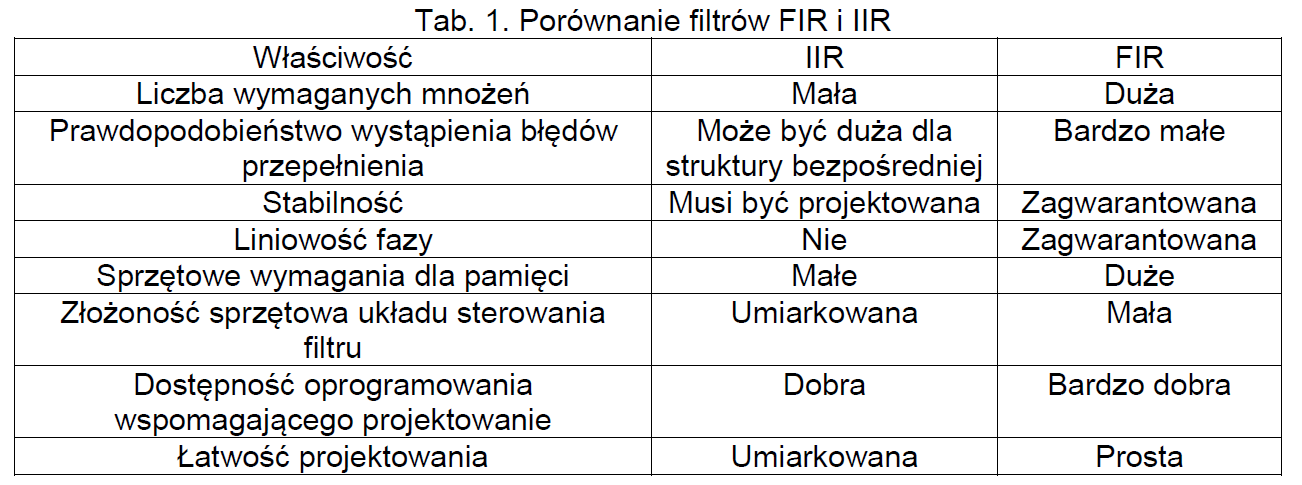

#### 3) Kiedy bardziej wskazane jest użycie filtru FIR a kiedy filtru IIR?

    Na przykład, jeśli wymagany jest filtr o dokładnie liniowej fazie, to jedynym poprawnym wyborem będzie filtr FIR. Jeżeli jednak wymagane jest, aby filtr pracował z bardzo wielką częstotliwością, a dopuszczalna jest niewielka nieliniowość fazy, możemy skłonić się ku filtrom IIR z ich zredukowaną liczbą operacji mnożenia dla jednej próbki sygnału\ wyjściowego.

#### 4) Czy są jakieś różnice w budowie filtrów FIR i IIR.

Tak, IIR mają sprzężenie zwrotne: